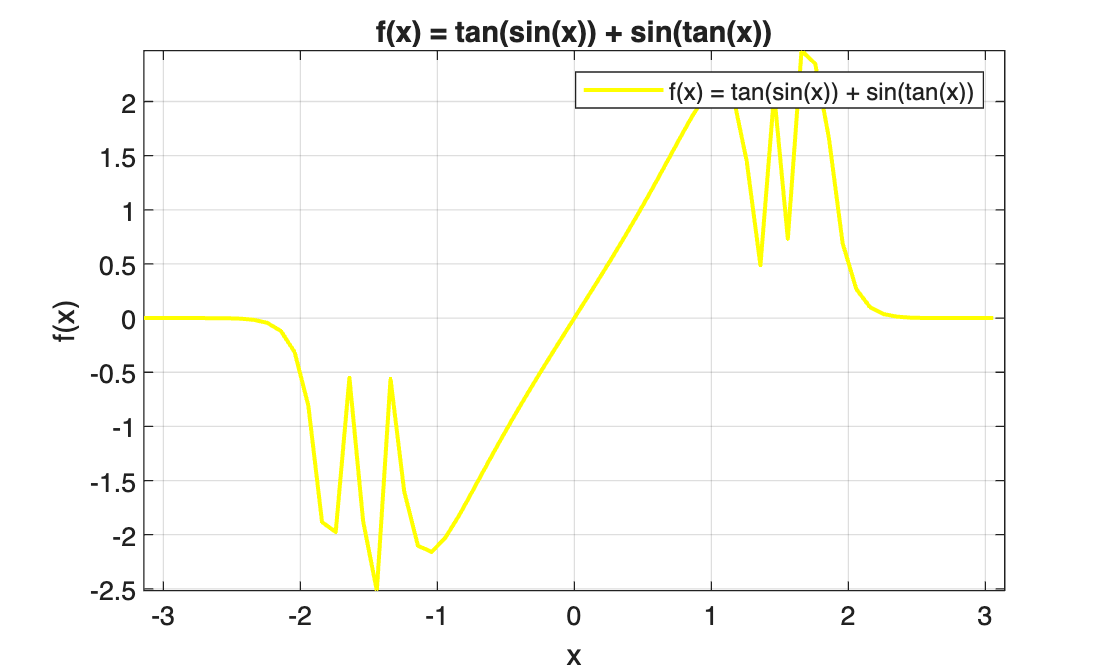

clear;
%a)Pirmas grafinis langas
x1= -pi:0.1:pi;
y1= tan(sin(x1))+ sin(tan(x1));
figure(1);
plot(x1, y1, 'y', 'LineWidth', 1.5);
axis([-pi pi min(y1) max(y1)]);
grid on;
%c)Pavadinimai 
title('f(x) = tan(sin(x)) + sin(tan(x))');
xlabel('x');
ylabel('f(x)');
legend('f(x) = tan(sin(x)) + sin(tan(x))');

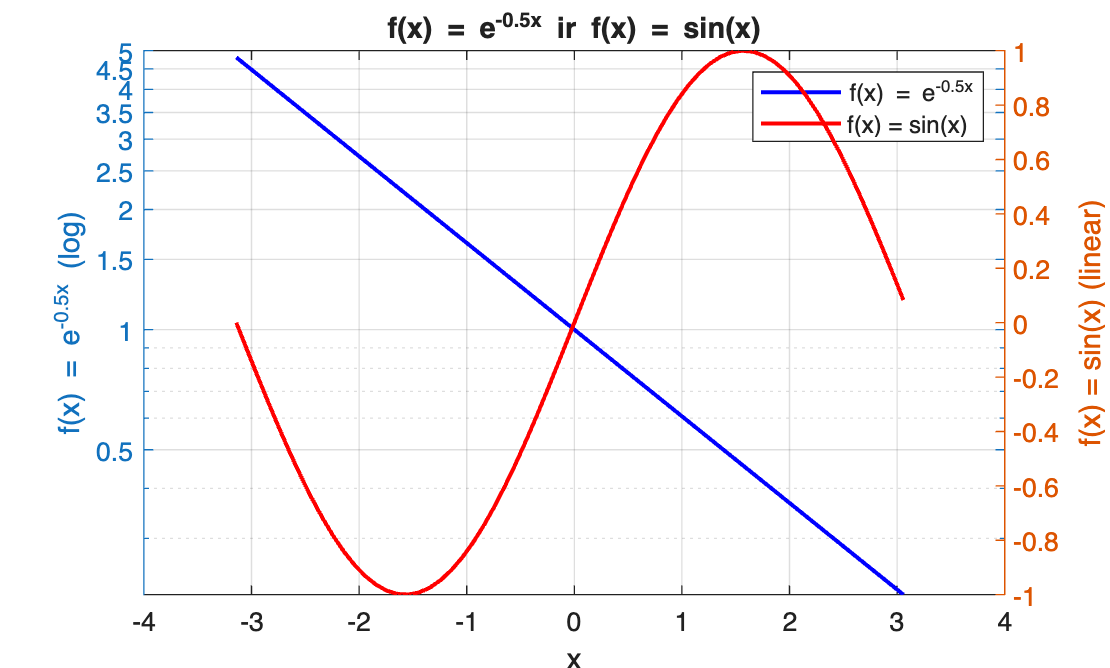

 
%b)Antras grafikas
x2 = -pi:0.1:pi;
y2a = exp(-0.5*x2);  
y2b = sin(x2);       
figure(2);
[AX, H1, H2] = plotyy(x2, y2a, x2, y2b);
set(AX(1), 'YScale', 'log');   
set(AX(2), 'YScale', 'linear');
set(H1, 'Color', 'b', 'LineWidth', 1.5);
set(H2, 'Color', 'r', 'LineWidth', 1.5);
grid on;
%c)Pavadinimai
title('f(x) = e^{-0.5x} ir f(x) = sin(x)');
xlabel('x');
ylabel(AX(1), 'f(x) = e^{-0.5x} (log)');
ylabel(AX(2), 'f(x) = sin(x) (linear)');
legend([H1, H2], {'f(x) = e^{-0.5x}', 'f(x) = sin(x)'});

clear
N= 6;
M= 4;
rng(1)
data= rand(N, M)

data =     0.4170    0.1863    0.2045    0.1404
    0.7203    0.3456    0.8781    0.1981
    0.0001    0.3968    0.0274    0.8007
    0.3023    0.5388    0.6705    0.9683
    0.1468    0.4192    0.4173    0.3134
    0.0923    0.6852    0.5587    0.6923


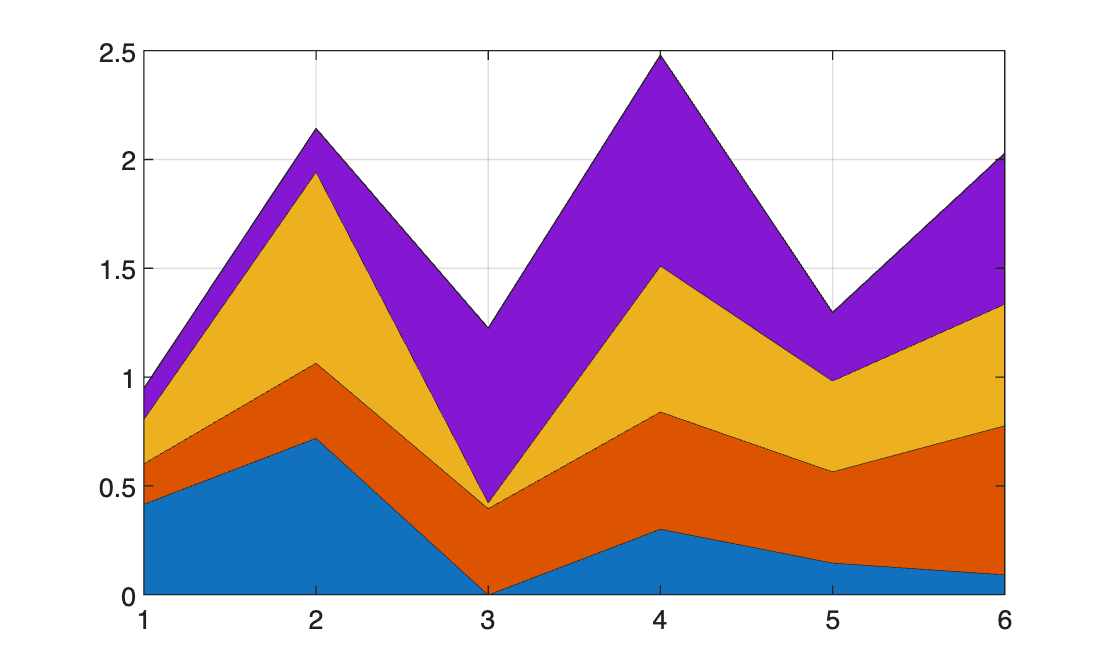

%a) 
figure(1);
area(1:N, data);
grid on;

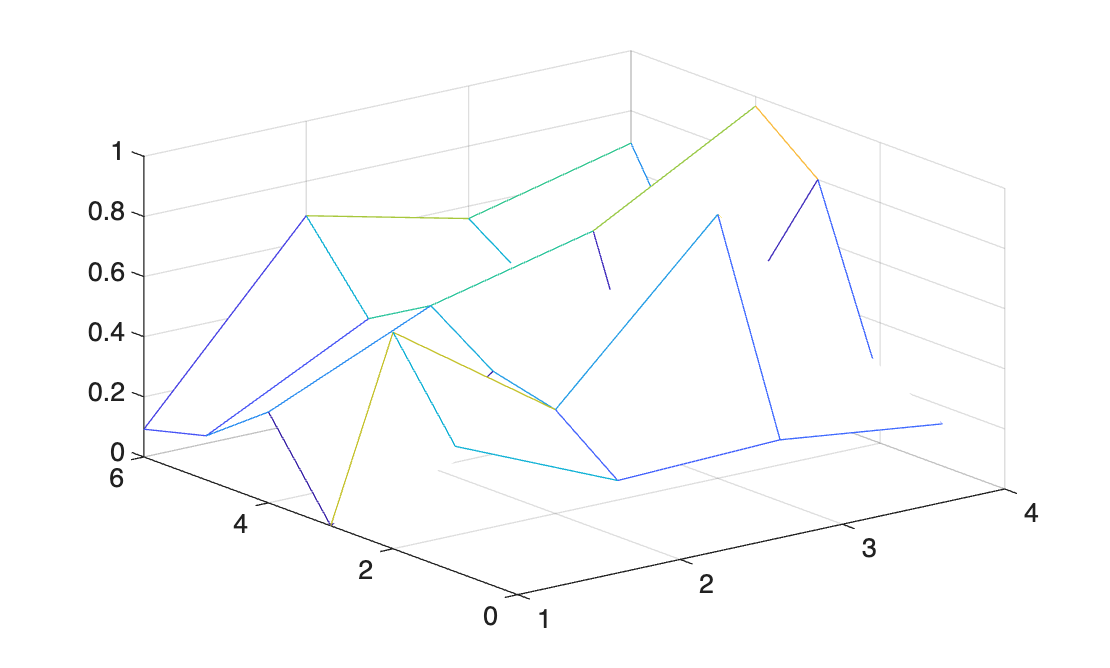

%b)
figure(2);
mesh(data)
grid on;

clear
%3. Praktinis veiksmų su masyvais taikymas
A=8; f=5; sigma= 1.8; U1= 5; U2= 3; t= 0 : 0.005 : 1.5;
s= A * cos(2*pi*f*t);
n= sigma * rand(size(t));
% Signalas su triukšmu
bendras_sig = s + n

bendras_sig =     9.5775    9.5118    7.7615    7.1984    6.7778    7.2375    4.8793    4.3899    4.1963    2.2112    1.2454   -0.6835   -1.2364   -2.1296   -4.6694   -4.3066   -4.6922   -5.7814   -7.1037   -6.4808   -7.8142   -7.0953   -5.9730   -6.5995   -5.9541   -5.4228   -4.6674   -2.4100   -2.0912   -0.7735    0.8848    1.3475    3.5055    3.8960    5.7630    6.9164    6.6563    7.8734    8.8584    8.6470    8.0899    8.8661    8.8033    8.0549    8.1724    6.7127    6.3284    3.8794    2.7228    2.7048


% a) Reikšmės, viršijančios U1 ribą
atrinktos_reiksmes = bendras_sig(bendras_sig > U1)

atrinktos_reiksmes =     9.5775    9.5118    7.7615    7.1984    6.7778    7.2375    5.7630    6.9164    6.6563    7.8734    8.8584    8.6470    8.0899    8.8661    8.8033    8.0549    8.1724    6.7127    6.3284    6.7677    7.0601    8.0768    9.2031    8.5446    9.6354    9.0236    7.6369    8.8010    7.7158    7.4520    5.0125    6.2567    7.0017    7.4734    7.3737    7.7163    8.1199    8.0802    8.0950    8.0147    8.4114    7.4796    5.6795    5.3730    6.3230    7.6056    7.5064    8.9634    8.0213    8.4686


% b) Filtravimas
filtruotas = bendras_sig

filtruotas =     9.5775    9.5118    7.7615    7.1984    6.7778    7.2375    4.8793    4.3899    4.1963    2.2112    1.2454   -0.6835   -1.2364   -2.1296   -4.6694   -4.3066   -4.6922   -5.7814   -7.1037   -6.4808   -7.8142   -7.0953   -5.9730   -6.5995   -5.9541   -5.4228   -4.6674   -2.4100   -2.0912   -0.7735    0.8848    1.3475    3.5055    3.8960    5.7630    6.9164    6.6563    7.8734    8.8584    8.6470    8.0899    8.8661    8.8033    8.0549    8.1724    6.7127    6.3284    3.8794    2.7228    2.7048


filtruotas(abs(filtruotas) < U2) = 0

filtruotas =     9.5775    9.5118    7.7615    7.1984    6.7778    7.2375    4.8793    4.3899    4.1963         0         0         0         0         0   -4.6694   -4.3066   -4.6922   -5.7814   -7.1037   -6.4808   -7.8142   -7.0953   -5.9730   -6.5995   -5.9541   -5.4228   -4.6674         0         0         0         0         0    3.5055    3.8960    5.7630    6.9164    6.6563    7.8734    8.8584    8.6470    8.0899    8.8661    8.8033    8.0549    8.1724    6.7127    6.3284    3.8794         0         0


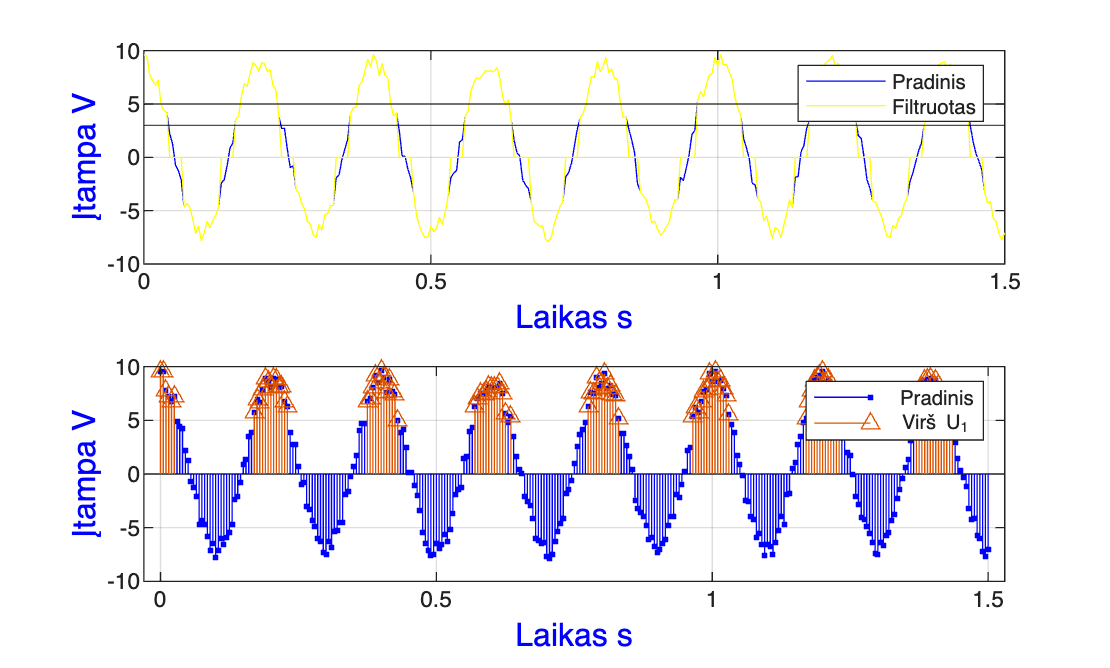


figure
subplot(2,1,1)
plot(t,bendras_sig,'b',t,filtruotas,'y')
yline(U1,'k-')
yline(U2,'k-')
grid on
xlabel('Laikas s','Color','b','FontSize',12)
ylabel('Įtampa V','Color','b','FontSize',12)
legend('Pradinis','Filtruotas')

subplot(2,1,2)
stem(t,bendras_sig,'b.')
hold on
stem(t(bendras_sig>U1),bendras_sig(bendras_sig>U1),'^')
grid on
xlabel('Laikas s','Color','b','FontSize',12)
ylabel('Įtampa V','Color','b','FontSize',12)
legend('Pradinis','Virš U_1')